%% 1. Create the vector x = [1,2,...,100]. 
% Assign the even numbers of x to a new vector y. 20 points

% Create the vector x
x = 1:100;

% Assign the even numbers of x to a new vector y
y = x(mod(x, 2) == 0);

% Display the results
disp('Vector x:');

Vector x:


disp(x);

     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100



disp('Vector y (even numbers):');

Vector y (even numbers):


disp(y);

     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98   100



%% 2. Use for loop to find the values of x(t) = 3 cos (2πft + 0.1) for t = 0, 0.1, 0.2, 0.3, 0.4 s when f=10, 15, and 20 Hz. 
% Use one set of statements to compute the values for all three frequencies and store the results in a two-dimensional array. 
% Use two nested for loops and double indexing. 20 points 

% Step 1: Define the frequencies and time vector
frequencies = [10, 15, 20]; % in Hz
time = 0:0.1:0.4; % time vector from 0 to 0.4 seconds with step of 0.1

% Step 2: Initialize the results array
results = zeros(length(frequencies), length(time));

% Step 3: Nested for loops to compute x(t) for each frequency and time
for i = 1:length(frequencies) % Loop over frequencies
    f = frequencies(i);
    for j = 1:length(time) % Loop over time values
        t = time(j);
        results(i, j) = 3 * cos(2 * pi * f * t + 0.1); % Compute x(t)
    end
end

% Step 4: Display the results
disp('Results (rows: frequencies, columns: time values):');

Results (rows: frequencies, columns: time values):


disp(results);

    2.9850    2.9850    2.9850    2.9850    2.9850
    2.9850   -2.9850    2.9850   -2.9850    2.9850
    2.9850    2.9850    2.9850    2.9850    2.9850



%% 3. Create a 15-element vector with values of x(t) = 4 cos(2πt + 0.2) + 3 sin(π2t) at equally spaced interval 0 ≤ t ≤ 1. 
% Find the maximum element value, the minimum element value, the average of the element values, and the indices of the elements for which the element magnitude is greater than 4. 20 points

% Step 1: Define the time vector with 15 equally spaced points from 0 to 1
t = linspace(0, 1, 15); % 15 points from 0 to 1

% Step 2: Compute the values of x(t)
x = 4 * cos(2 * pi * t + 0.2) + 3 * sin(pi * 2 * t);

% Step 3: Find the maximum and minimum values
max_value = max(x);
min_value = min(x);

% Step 4: Calculate the average value
average_value = mean(x);

% Step 5: Find indices of elements with magnitude greater than 4
indices_greater_than_4 = find(abs(x) > 4);

% Display the results
disp('Maximum Value:');

Maximum Value:


disp(max_value);

    4.4889



disp('Minimum Value:');

Minimum Value:


disp(min_value);

   -4.4889



disp('Average Value:');

Average Value:


disp(average_value);

    0.2614



disp('Indices of elements with magnitude greater than 4:');

Indices of elements with magnitude greater than 4:


disp(indices_greater_than_4);

     2     3     9    10



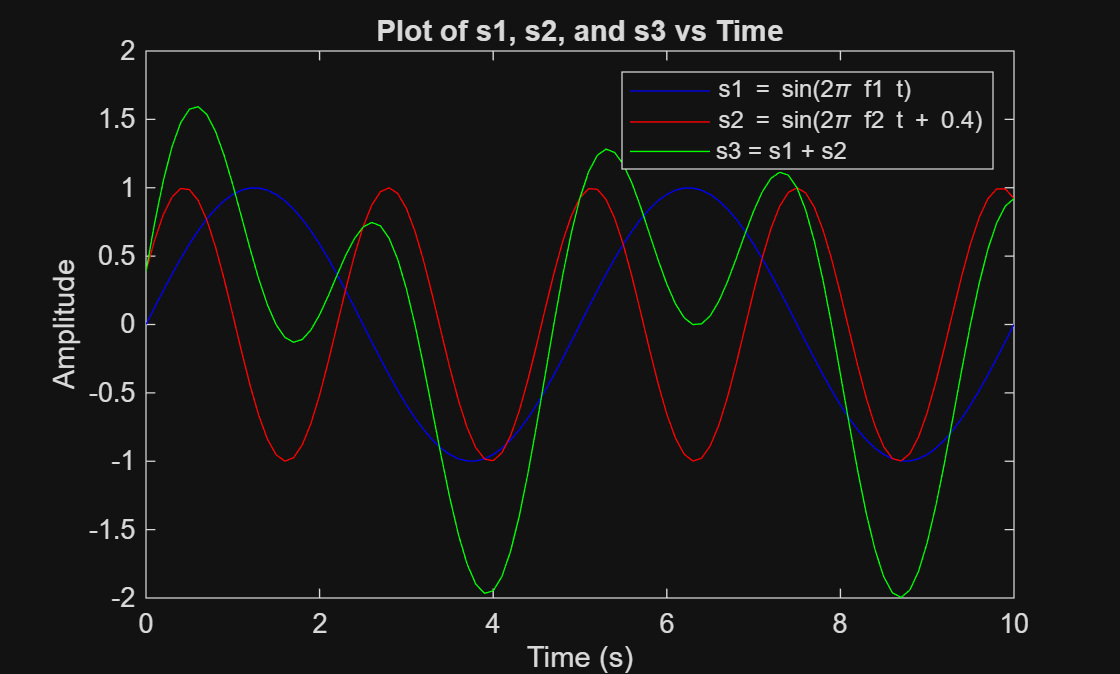

%% 4. Assume s1 = sin(2πf1t), s2 = sin(2πf2t + 0.4) and s3 = s1 + s2, where f1 = 0.2 and f2 = 0.425. 
% Plot s1,s2, and s3 v/s t with t = 0 : 0.1 : 10 on the same graph (you have to use hold on command). 
% Label the axes and create legends for each graph. 20 points

% Step 1: Define the frequency variables
f1 = 0.2; % Frequency for s1
f2 = 0.425; % Frequency for s2

% Step 2: Create the time vector
t = 0:0.1:10; % Time from 0 to 10 with step of 0.1

% Step 3: Calculate the functions
s1 = sin(2 * pi * f1 * t); % s1
s2 = sin(2 * pi * f2 * t + 0.4); % s2
s3 = s1 + s2; % s3

% Step 4: Plot the functions
figure; % Create a new figure
plot(t, s1, 'b', 'DisplayName', 's1 = sin(2\pi f1 t)'); % Plot s1 in blue
hold on; % Retain current plot
plot(t, s2, 'r', 'DisplayName', 's2 = sin(2\pi f2 t + 0.4)'); % Plot s2 in red
plot(t, s3, 'g', 'DisplayName', 's3 = s1 + s2'); % Plot s3 in green

% Step 5: Label the axes and create legends
xlabel('Time (s)'); % Label for x-axis
ylabel('Amplitude'); % Label for y-axis
title('Plot of s1, s2, and s3 vs Time'); % Title of the plot
legend show; % Show legend
hold off; % Release the hold on the current plot

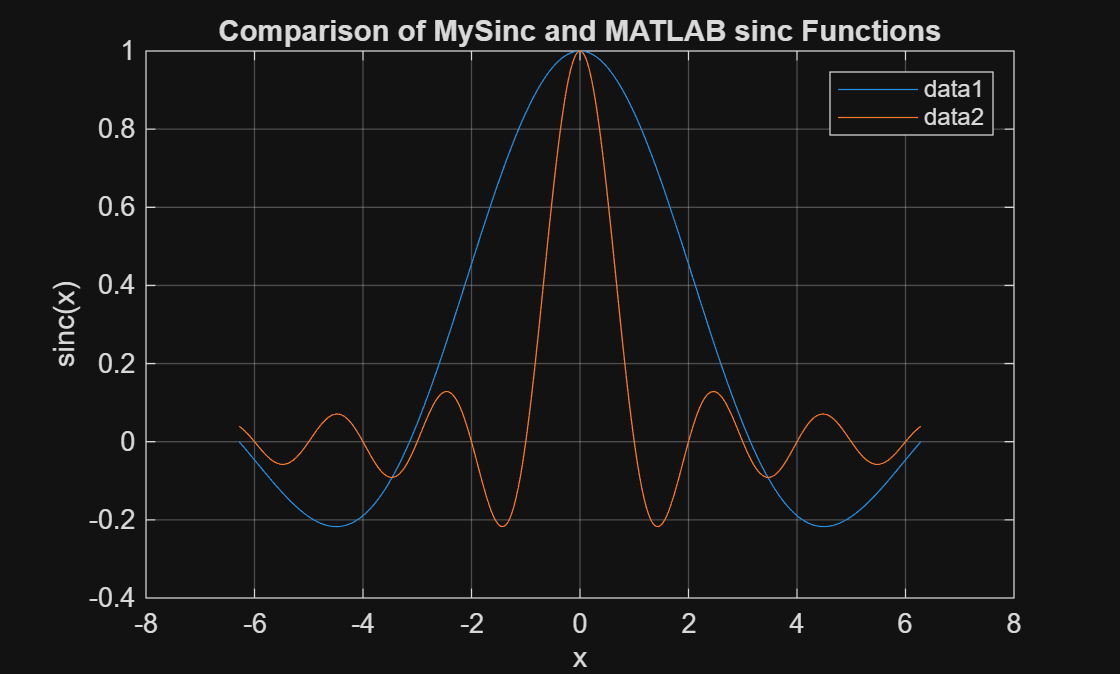

%% 5. Sinc function is a function that arises frequently in our course. 
% It is defined as sinc(x) = 1 for x=0, sin(x)/x otherwise. 
% Create a Matlab function MySinc () that defines sinc(x) function following the above definition. 
% Plot the value sinc(x) in the interval [-2π 2π] using MySinc () function and Matlab inbuilt sinc() function on the same graph. 20 points 

%function MySinc:
function y = MySinc(x)
    % Custom sinc function definition
    y = zeros(size(x)); % Initialize output
    y(x == 0) = 1; % Define sinc(0) = 1
    y(x ~= 0) = sin(x(x ~= 0)) ./ x(x ~= 0); % Define sinc(x) = sin(x)/x for x != 0
end

%Plotting Script:
% Step 1: Create the x vector
x= linspace(-2*pi, 2*pi, 1000); % 1000 points from -2π to 2π
x_sym=sym(x);
% Step 2: Compute the values using MySinc and built-in sinc
y_mySinc = MySinc(x); % Custom sinc function
y_builtinSinc = sinc(x_sym); % MATLAB's built-in sinc function (normalized)

% Step 3: Plot the results
figure; % Create a new figure
plot(x, y_mySinc);
hold on; % Retain current plot
plot(x, y_builtinSinc); % Plot built-in sinc in red
hold off; % Release the hold

% Step 4: Label the axes and create legends
xlabel('x'); % Label for x-axis
ylabel('sinc(x)'); % Label for y-axis
title('Comparison of MySinc and MATLAB sinc Functions'); % Title of the plot
legend show; % Show legend
grid on; % Add grid for better visibility

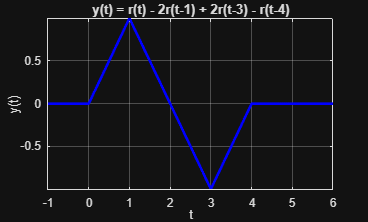

% Define time vector
t = linspace(-1, 6, 1000);  % Time range covering all shifts

% Define the ramp function
ramp = @(t) t .* (t >= 0);  % r(t) = t * u(t)

% Define y(t) using ramp function components
y = ramp(t) ...
    - 2 * ramp(t - 1) ...
    + 2 * ramp(t - 3) ...
    - ramp(t - 4);

% Plot the result
figure;
plot(t, y, 'b', 'LineWidth', 2);
xlabel('t');
ylabel('y(t)');
title('y(t) = r(t) - 2r(t-1) + 2r(t-3) - r(t-4)');
grid on;
axis tight;